%Campo magnetico que se genera en el cable
clc
clear all
r=1,

r = 1

k=1e-07;
I=2 %amp

I = 2

%L=[0.0075*pi*2,0,0]
largo=r

largo = 1


nn=1000 %Numero de dL's

nn = 1000

%x=linspace(-r/2,r/2,nn);
%%% Velocidad de la Posicion de la carga

% x=linspace(0.1,r,nn)
% y=zeros(1,nn);
% z=zeros(1,nn);
h=2

h = 2

p=0.02

p = 0.0200

t=linspace(0,2*pi*h/p,nn)

t =          0    0.6289    1.2579    1.8868    2.5158    3.1447    3.7737    4.4026    5.0316    5.6605    6.2895    6.9184    7.5474    8.1763    8.8053    9.4342   10.0632   10.6921   11.3211   11.9500   12.5789   13.2079   13.8368   14.4658   15.0947   15.7237   16.3526   16.9816   17.6105   18.2395   18.8684   19.4974   20.1263   20.7553   21.3842   22.0132   22.6421   23.2711   23.9000   24.5290   25.1579   25.7868   26.4158   27.0447   27.6737   28.3026   28.9316   29.5605   30.1895   30.8184


x=r*cos(t)

x =     1.0000    0.8086    0.3078   -0.3108   -0.8105   -1.0000   -0.8068   -0.3048    0.3138    0.8123    1.0000    0.8049    0.3018   -0.3168   -0.8142   -1.0000   -0.8031   -0.2988    0.3198    0.8160    0.9999    0.8012    0.2958   -0.3227   -0.8178   -0.9999   -0.7993   -0.2928    0.3257    0.8196    0.9998    0.7974    0.2898   -0.3287   -0.8214   -0.9998   -0.7955   -0.2868    0.3317    0.8232    0.9997    0.7936    0.2838   -0.3346   -0.8250   -0.9996   -0.7917   -0.2808    0.3376    0.8267


y=r*sin(t)

y =          0    0.5883    0.9514    0.9505    0.5857   -0.0031   -0.5908   -0.9524   -0.9495   -0.5832    0.0063    0.5934    0.9534    0.9485    0.5806   -0.0094   -0.5959   -0.9543   -0.9475   -0.5781    0.0126    0.5984    0.9552    0.9465    0.5755   -0.0157   -0.6009   -0.9562   -0.9455   -0.5729    0.0189    0.6034    0.9571    0.9444    0.5704   -0.0220   -0.6060   -0.9580   -0.9434   -0.5678    0.0252    0.6084    0.9589    0.9424    0.5652   -0.0283   -0.6109   -0.9598   -0.9413   -0.5626


z=(t*p)/(2*pi)

z =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0501    0.0521    0.0541    0.0561    0.0581    0.0601    0.0621    0.0641    0.0661    0.0681    0.0701    0.0721    0.0741    0.0761    0.0781    0.0801    0.0821    0.0841    0.0861    0.0881    0.0901    0.0921    0.0941    0.0961    0.0981



plot3(x,y,z,'color',[0.9100    0.4100    0.1700],'MarkerSize',20)%Cable
axis equal
hold on

%pq=[[0];[0];[0.1]]
%pq=[x;y;z]; %%% Posición de las cargas

%Meshgrid
n=10

n = 10

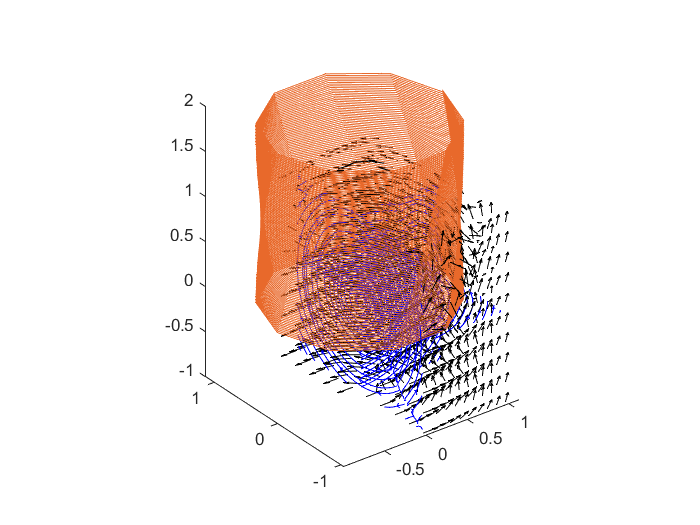

xx=linspace(0,r,n);
yy=linspace(-r,r,n);
zz=linspace(-r,r,n);

%%%%%%
[X,Y,Z]=meshgrid(xx,yy,zz);
distx=X*0;
disty=Y*0;
distz=Z*0;

for i=1:nn 
        distx=[distx;X-x(i)];
        disty=[disty;Y-y(i)];
        distz=[distz;Z-z(i)];
        %disty=Y-pq(2,:);
        %distz=Z-pq(3,:);
end

r=sqrt(distx(n+1:end,:,:).^2+disty(n+1:end,:,:).^2+distz(n+1:end,:,:).^2);
distx=distx(n+1:end,:,:);
disty=disty(n+1:end,:,:);
distz=distz(n+1:end,:,:);

Bx=X*0;
By=Y*0;
Bz=Z*0;
kk=0:nn-1;
dx=distx;
dy=disty;
dz=distz;
for j=1:nn %dL
    km=n*kk(j);
    L=[x(j),y(j),z(j)];
    L=L/norm(L);
    distx=dx(km+1:km+n,:,:);
    disty=dy(km+1:km+n,:,:);
    distz=dz(km+1:km+n,:,:);
    rr=r(km+1:km+n,:,:);
    for i2=1:n^3 %distancia
        ri=([distx(i2),disty(i2),distz(i2)]);
        ll=cross(L,ri);
        Bx(i2)=Bx(i2)+((k*I*(ll(1)))./rr(i2)^3);
        By(i2)=By(i2)+((k*I*(ll(2)))./rr(i2)^3);
        Bz(i2)=Bz(i2)+((k*I*(ll(3)))./rr(i2)^3);   
    end
end

B=sqrt(Bx.^2+By.^2+Bz.^2);
Bx1=Bx./B;
By1=By./B;
Bz1=Bz./B;

quiver3(X,Y,Z,Bx1,By1,Bz1,'k'); %Vectores unitarios
%quiver3(X,Y,Z,Bx,By,Bz,'k',"AutoScaleFactor",5)
streamslice(X,Y,Z,Bx,By,Bz,[0 10],[0 10],[0 10])
axis equal